## Quiz 6 Practice : Nonlinear Equations and Optimization

Question 1: 

Consider the equation:


$$f\left(x\right)=\frac{\left(x-2\right)\left(2x+1\right)}{1+x^2 }$$


Use Newton’s method to find the zeros of f(x) from -5 to 5 and the x-values at which this occurs.

Hint: Choose a proper x0 based on the graph to find one and run again to find the other.

clear; clc; close all;

% Set up the initial guess and tolerance for Newton's method
xr = -1;             % Initial guess for the first root (choose based on the graph)
maxTol = 0.01;       % Tolerance for stopping criterion
maxIter = 20;        % Maximum number of iterations to avoid infinite loops
tspan = [-5, 5];     % Range for plotting

% Define the function and its derivative
syms f(x);
f(x) = (x - 2) * (2 * x + 1) / (1 + x^2);  % Function definition
dfx(x) = diff(f, x);                       % Derivative of the function

% Plot the function to identify potential starting points
figure;
fplot(f, tspan, 'LineWidth', 2);
hold on
xlabel('x');
ylabel('f(x)');
title('Finding Zeros of f(x) Using Newton’s Method');
yline(0, 'LineWidth', 1, 'Color', 'k');  % Add y=0 line for reference
grid on;

% Run Newton's method
fprintf('Starting Newton’s method with initial guess: xr = %.2f\n', xr);

Starting Newton’s method with initial guess: xr = -1.00


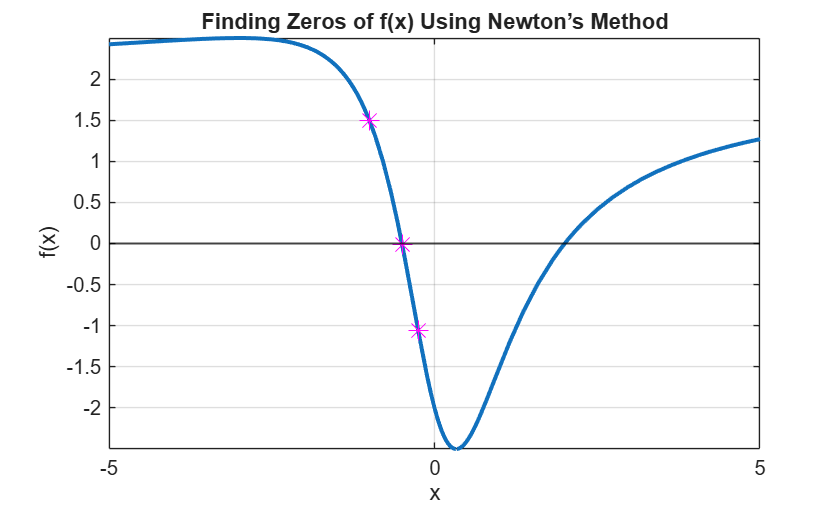

Iteration 1: x = -0.2500, f(x) = 1.5000
Iteration 2: x = -0.4984, f(x) = -1.0588
Iteration 3: x = -0.5000, f(x) = -0.0065


Zero found at x = -0.5000 within tolerance 0.01


for itr = 1:maxIter
    % Plot guess for zero
    plot(xr,f(xr),'m*','MarkerSize',10);
    % Calculate the function and derivative values at the current guess
    f_val = double(f(xr));
    dfx_val = double(dfx(xr));
    
    % Avoid division by zero in case derivative is zero
    if dfx_val == 0
        fprintf('Derivative is zero at x = %.4f. Stopping to avoid division by zero.\n', xr);
        break;
    end
    
    % Newton's method formula
    xr_new = xr - f_val / dfx_val;
    
    % Display iteration results
    fprintf('Iteration %d: x = %.4f, f(x) = %.4f\n', itr, xr_new, f_val);
    
    % Check for convergence
    if abs(f_val) <= maxTol
        fprintf('Zero found at x = %.4f within tolerance %.2f\n', xr_new, maxTol);
        break;
    end
    
    % Update x value for the next iteration
    xr = xr_new;
end

Question 2: 

Use SGD code needed to find the minimum and maximum in a span from -5 to 5 of the function:


$$f\left(x\right)=\frac{\left(x-2\right)\left(2x+1\right)}{1+x^2 }$$


Use a tolerance of 0.01 and a step of 0.1.

Hint: Changing the sign switches the direction. Choose a proper x0 to avoid local minima/maxima.

A) Minimum?

clear; clc; close all;

% Setup parameters
tolx = 0.01;             % Tolerance for convergence
alpha = 0.1;             % Step size (learning rate)
tspan = [-5, 5];         % Range for plotting
maxloops = 100;           % Maximum number of iterations

% Define the function and its gradient/second derivative
syms f(x);
f(x) = (x - 2) * (2 * x + 1) / (1 + x^2);   % Function definition
dfx(x) = diff(f, x);                    % Gradient (first derivative)
d2fx(x) = diff(f, x, 2);                    % Second derivative

% Plot the function to visualize the initial estimate
figure;
fplot(f,tspan, 'LineWidth', 2);
xlabel('x');
ylabel('f(x)');
title('SGD Optimization to Find Local Minima');
grid on;
hold on;

% Initialize first starting point and loop to find a local minimum or maximum
x0 = -2;
fprintf('Starting SGD from x0 = %.2f\n', x0);

Starting SGD from x0 = -2.00


for ii = 1:maxloops
    % Plot the current point on the function
    plot(x0, f(x0), 'm*', 'MarkerSize', 10);

    % Evaluate the gradient at the current point
    gradValue = double(dfx(x0));

    % Update x using SGD step
    x1 = x0 - alpha * gradValue;

    % Display the iteration results
    if ii == 1
        fprintf('Ite   X0       X1       GFx\n');
    end
    fprintf('%2d   %7.3f   %7.3f   %7.3f\n', ii, x0, x1, gradValue);

    % Check if convergence criterion is met
    if abs(x1 - x0) <= tolx
        % Determine whether we have a local minimum or maximum based on the second derivative
        secondDeriv = double(d2fx(x1));
        if secondDeriv > 0
            disp('Local Minimum found');
        elseif secondDeriv < 0
            disp('Local Maximum found');
        else
            disp('Saddle Point or inflection point found');
        end
        break;
    end

    % Update x0 for the next iteration
    x0 = x1;
end

Ite   X0       X1       GFx


 1    -2.000    -1.972    -0.280
 2    -1.972    -1.942    -0.297
 3    -1.942    -1.911    -0.317
 4    -1.911    -1.877    -0.339
 5    -1.877    -1.840    -0.364
 6    -1.840    -1.801    -0.393
 7    -1.801    -1.758    -0.426
 8    -1.758    -1.712    -0.465
 9    -1.712    -1.661    -0.512
10    -1.661    -1.604    -0.568
11    -1.604    -1.540    -0.636
12    -1.540    -1.468    -0.722
13    -1.468    -1.385    -0.832
14    -1.385    -1.287    -0.978
15    -1.287    -1.169    -1.180
16    -1.169    -1.022    -1.473
17    -1.022    -0.829    -1.925
18    -0.829    -0.564    -2.658
19    -0.564    -0.186    -3.776
20    -0.186     0.224    -4.096
21     0.224     0.320    -0.962
22     0.320     0.331    -0.110
23     0.331     0.333    -0.020


Local Minimum found


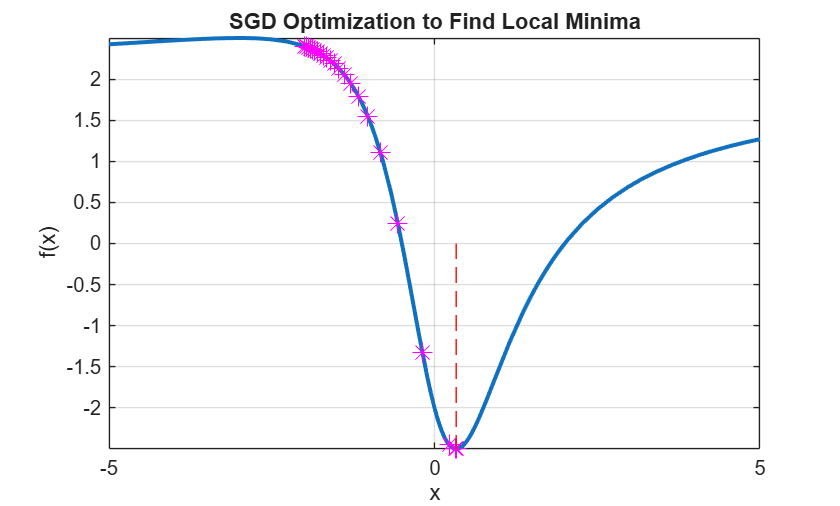

% Plot the final result
line([x1 x1], [0 f(x1)], 'Color', 'red', 'LineStyle', '--');

B) Maximum?

% Setup parameters
x0 = -1;              % Starting point for SGD
% Plot the function to visualize the shape and initial estimate
figure;
fplot(f, tspan, 'LineWidth', 2);
xlabel('x');
ylabel('f(x)');
title('SGD Optimization to Find Local Maximum');
grid on;
hold on;

% SGD loop to find the local maximum
fprintf('Starting SGD from x0 = %.2f\n', x0);

Starting SGD from x0 = -1.00


for ii = 1:maxloops
    % Plot the current point on the function
    plot(x0, f(x0), 'm*', 'MarkerSize', 10);

    % Evaluate the gradient at the current point
    gradValue = double(dfx(x0));

    % Update x for gradient ascent (move opposite to gradient descent direction)
    x1 = x0 + alpha * gradValue;

    % Display iteration details
    if ii == 1
        fprintf('Ite   X0       X1       DFx        D2Fx\n');
    end
    fprintf('%2d   %7.3f   %7.3f   %7.3f\n', ii, x0, x1, gradValue);

    % Check if convergence criterion is met
    if abs(x1 - x0) <= tolx
        % Use second derivative test to determine if it's a maximum
        secondDeriv = double(d2fx(x1));
        if secondDeriv < 0
            disp('Local Maximum found');
        elseif secondDeriv > 0
            disp('Local Minimum found');
        else
            disp('Saddle Point or inflection point found');
        end
        break;
    end

    % Update x0 for the next iteration
    x0 = x1;
end

Ite   X0       X1       DFx        D2Fx


 1    -1.000    -1.200    -2.000
 2    -1.200    -1.339    -1.391
 3    -1.339    -1.446    -1.068
 4    -1.446    -1.533    -0.868
 5    -1.533    -1.606    -0.732
 6    -1.606    -1.669    -0.633
 7    -1.669    -1.725    -0.558
 8    -1.725    -1.775    -0.498
 9    -1.775    -1.820    -0.450
10    -1.820    -1.861    -0.410
11    -1.861    -1.898    -0.377
12    -1.898    -1.933    -0.348
13    -1.933    -1.966    -0.323
14    -1.966    -1.996    -0.302
15    -1.996    -2.024    -0.283
16    -2.024    -2.051    -0.266
17    -2.051    -2.076    -0.251
18    -2.076    -2.099    -0.237
19    -2.099    -2.122    -0.225
20    -2.122    -2.143    -0.214
21    -2.143    -2.164    -0.203
22    -2.164    -2.183    -0.194
23    -2.183    -2.202    -0.186
24    -2.202    -2.219    -0.178
25    -2.219    -2.236    -0.170
26    -2.236    -2.253    -0.163
27    -2.253    -2.268    -0.157
28    -2.268    -2.283    -0.151
29    -2.283    -2.298    -0.146
30    -2.298    -2.312    -0.140
31    -2.3

Local Maximum found


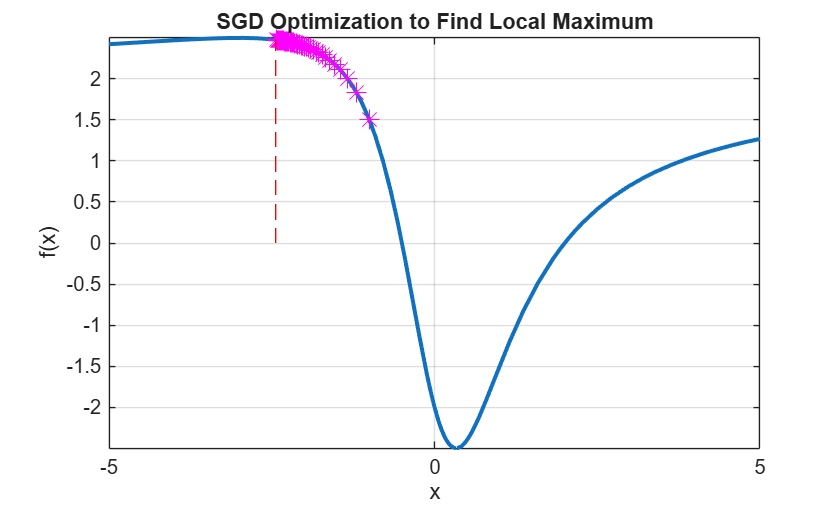

% Plot the final result with a vertical line at the detected maximum
line([x1 x1], [0 f(x1)], 'Color', 'red', 'LineStyle', '--');
hold off;

Question 3:

You are investigating the relationship between the diameter of small blood vessels (capillaries or arterioles) and the blood flow rate in a microvascular network. The goal is to model the blood flow in relation to vessel diameter using experimental data.

Blood flow in small vessels is typically governed by the Poiseuille's Law, which describes how flow rate $Q$ depends on the radius $r$ of a cylindrical vessel:


$$Q=\frac{\pi r^4 \Delta \;P}{8\mu \;L}$$


where:

- $Q$ is the flow rate

- $\Delta \;P$ is the pressure difference across a vessel

- $r$ is the radius of the vessel

- $\mu \;$ is the dynamic viscosity of the blood

- $L$ is the length of the vessel

However, in a microvascular network, the pressure difference and length may vary. A more generalized empirical form of this equation can be used for fitting, which relates the flow to the diameter of the vessels with an exponent $n$:


$$Q\left(d\right)={C\cdot d}^n$$


where:

- $Q$ is the flow rate

- $d$ is the diameter of the vessel

- $C$ is a lumped parameter that depends on viscosity and vessel length.

- $n$ is an exponent that represents the non-linearity of flow with respect to diameter.

You have experimental data collected from a microvascular system where the blood flow rate in different vessels (in mL/min) is measured along with their diameters (in micrometers).

Fit the equation $Q={C\cdot d}^n$ to the experimental data and estimate the values of $C$ and $n$, use an initial guess of $C=0\ldotp 1$ and $n=1$. Hint: Use fminsearch().

clear,clc
% Experimental data
diameters = [10 20 30 40 50 60 70 80]; % Diameter (µm)
flow_rate = [0.05 0.15 0.30 0.50 0.80 1.20 1.80 2.50]; % Flow Rate (mL/min)

% Model function: Q = C * d^n
Q_model = @(d, c) c(1) * d.^c(2);

% Objective function: sum of squared errors
SSE = @(c) sum((Q_model(diameters, c) - flow_rate).^2);

% Initial guess for parameters [C, n]
x0 = [0.1, 1]; % Initial guess: C = 0.1, n = 1

% Run optimization to find the best-fit parameters
params_opt = fminsearch(SSE, x0);

% Display the optimal parameters
fprintf('Optimal Parameters:\n');

Optimal Parameters:


fprintf('C: %d\n', params_opt(1));

C: 8.041603e-05


fprintf('n: %3.2f\n', params_opt(2));

n: 2.36


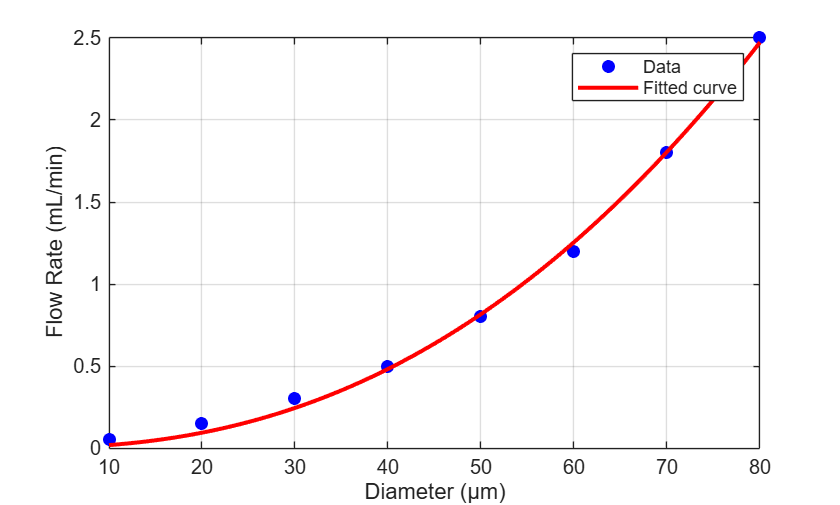

% Plot the fitted curve along with the data
figure;
plot(diameters, flow_rate, 'bo', 'MarkerFaceColor', 'b'); % Experimental data
hold on;
smooth_diameters=linspace(min(diameters), max(diameters));
fitted_flow = Q_model(smooth_diameters, params_opt);
plot(smooth_diameters, fitted_flow, 'r-', 'LineWidth', 2); % Fitted curve
xlabel('Diameter (µm)');
ylabel('Flow Rate (mL/min)');
legend('Data', 'Fitted curve');
grid on;
hold off;

Question 4:

In enzyme kinetics, substrate inhibition occurs when an excess of substrate reduces the reaction rate. The rate $v$ as a function of substrate concentration $\left\lbrack S\right\rbrack$ can be described by a non-linear equation:


$$v\left(\left\lbrack S\right\rbrack \right)=\frac{V_{\mathrm{Max}} \left\lbrack S\right\rbrack }{K_m +\left\lbrack S\right\rbrack +\frac{{\left\lbrack S\right\rbrack }^2 }{K_i }}$$


where:

- $v$ is the reaction rate

- $\left\lbrack S\right\rbrack$ is the substrate concentration

- $V_{\mathrm{Max}}$ is the maximum reaction rate

- $K_m$ is the Michaelis constant (substrate concentration at half-maximal velocity)

- $K_i$ is the inhibition constant

Fit the equation above to the provided experimental data and estimate the values of $V_{\mathrm{Maxx}}$, $K_m$, and $K_i$. Use an initial guess of $V_{\mathrm{Nax}} =8$, $K_m =1\ldotp 5$, and $K_i =15$.

clear,clc

% Known substrate concentrations (S) and reaction rates (v)
S = [0.1, 0.5, 1.0, 2.0, 5.0, 10.0, 20.0, 50.0]; % Substrate concentrations in mM
v = [0.48, 2.12, 3.45, 5.20, 6.75, 7.85, 8.40, 8.60]; % Reaction rates in mM/s

% Non-linear model function for substrate inhibition:
% c(1) = Vmax (maximum reaction rate)
% c(2) = Km (Michaelis constant)
% c(3) = Ki (substrate inhibition constant)
model = @(S, c) (c(1) .* S) ./ (c(2) + S + (S.^2 ./ c(3)));

% Initial guess for the parameters [Vmax, Km, Ki]
initial_guess = [8, 1.5, 15];
% Objective function: Sum of squared errors (SSE) between model and data
SSE = @(c) sum((v - model(S, c)).^2);
% Minimize SSE to estimate model parameters
estimated_params = fminsearch(SSE, initial_guess);
% Display the estimated parameters
fprintf('Optimal Parameters:\n');

Optimal Parameters:


fprintf('Vmax = %3.2f\n', estimated_params(1)); % Display Vmax

Vmax = 9.14


fprintf('Km = %3.2f\n', estimated_params(2));   % Display Km

Km = 1.62


fprintf('Ki = %3.2f\n', estimated_params(3));   % Display Ki

Ki = 1731.02


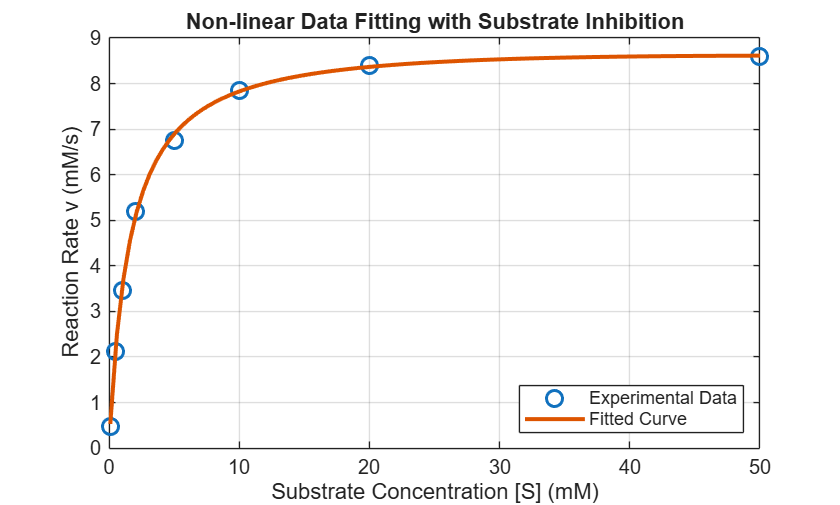

% Generate fine-grained substrate concentrations for smooth plotting
S_fine = linspace(min(S), max(S));
% Calculate the fitted reaction rates using the optimized parameters
v_fit = model(S_fine, estimated_params);
% Create a figure for visualization
figure;
plot(S, v, 'o', 'MarkerSize', 8, 'LineWidth', 1.5); % Plot experimental data
hold on;
plot(S_fine, v_fit, '-', 'LineWidth', 2);          % Plot fitted curve
legend('Experimental Data', 'Fitted Curve', 'Location', 'southeast');
xlabel('Substrate Concentration [S] (mM)');         % Label x-axis
ylabel('Reaction Rate v (mM/s)');                   % Label y-axis
title('Non-linear Data Fitting with Substrate Inhibition'); % Plot title
grid on;                                            % Enable grid
hold off;

Question 5:

Newton's Law of Cooling describes the rate at which the temperature of an object changes when it is exposed to an environment with a constant temperature. The equation is:


$$T\left(t\right)=T_{\mathrm{Env}} +\left(T_0 -T_{\mathrm{Env}} \right)e^{-\mathrm{kt}}$$


where:

- $T\left(t\right)$ is the temperature of the object at time $t$

- $t$ is time

- $T_{\mathrm{Env}}$ is the ambient (environment) temperature

- $T_0$ is the initial temperature of the object

- $k$ is the cooling constant (rate of cooling)

Fit the equation above to the provided experimental data for the temperature of a metal object as it cools over time and estimate the values of $T_{\mathrm{Env}}$, $T_0$, and $k$. Use an initial guess of $T_{\mathrm{Env}} =10$, $T_0 =80$, and $k=0\ldotp 5$.

clear;clc;
% Time (t) in minutes
t = [0, 2, 4, 6, 8, 10];

% Measured temperature (T) in °C
T = [100.0, 80.4, 65.2, 54.5, 47.1, 41.5];


% Non-linear cooling model:
% c(1) = T_env (ambient temperature)
% c(2) = T_0 (initial temperature of the object)
% c(3) = k (cooling constant)
model = @(t, c) c(1) + (c(2) - c(1)) .* exp(-c(3) .* t);


% Initial guess for the parameters [T_env, T_0, k]
initial_guess = [10, 80, 0.5];

% Objective function: Sum of squared errors (SSE) between model and data
SSE = @(c) sum((T - model(t, c)).^2);

% Minimize SSE to estimate model parameters
estimated_params = fminsearch(SSE, initial_guess);

% Display the estimated parameters
disp('Estimated Parameters:');

Estimated Parameters:


disp(['T_env = ', num2str(estimated_params(1)), ' °C']); % Ambient temperature

T_env = 26.5399 °C


disp(['T_0 = ', num2str(estimated_params(2)), ' °C']);   % Initial temperature

T_0 = 100.1454 °C


disp(['k = ', num2str(estimated_params(3)), ' 1/min']); % Cooling constant

k = 0.15988 1/min


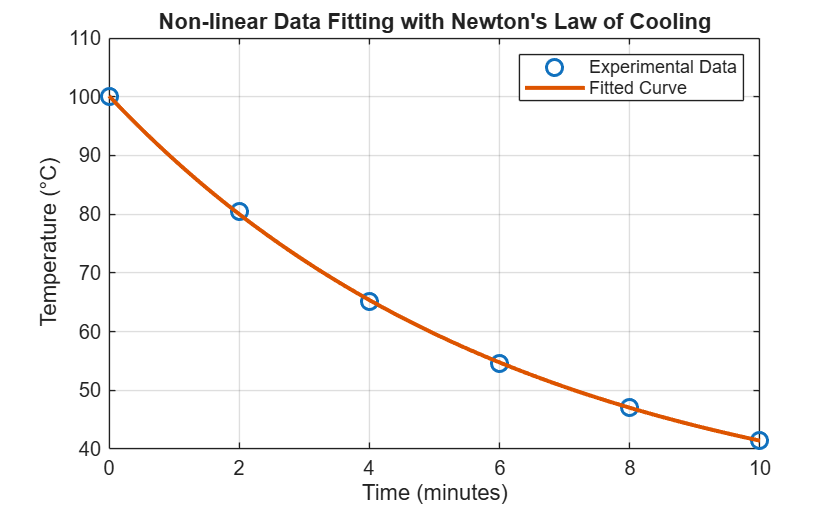


% Generate fine-grained time points for smooth plotting
t_fine = linspace(min(t), max(t), 100);

% Calculate the fitted temperatures using the optimized parameters
T_fit = model(t_fine, estimated_params);

% Create a figure for visualization
figure;
plot(t, T, 'o', 'MarkerSize', 8, 'LineWidth', 1.5); % Plot experimental data
hold on;
plot(t_fine, T_fit, '-', 'LineWidth', 2);           % Plot fitted curve
legend('Experimental Data', 'Fitted Curve', 'Location', 'northeast');
xlabel('Time (minutes)');                           % Label x-axis
ylabel('Temperature (°C)');                         % Label y-axis
title('Non-linear Data Fitting with Newton''s Law of Cooling'); % Plot title
grid on;                                            % Enable grid
hold off;